clear;
dtheta = 2*pi/128;
r = 1; theta = (0:dtheta:2*pi-dtheta)';
basisIdx = find(theta == 0 | theta == pi/2);
x = r*cos(theta); y = r*sin(theta);
v = [x, y]';
A = [2, 1; -1, 1], vv = A*v

A =      2     1
    -1     1


vv =     2.0000    2.0467    2.0884    2.1251    2.1567    2.1830    2.2042    2.2200    2.2304    2.2355    2.2352    2.2296    2.2185    2.2021    2.1804    2.1535    2.1213    2.0841    2.0418    1.9946    1.9426    1.8859    1.8247    1.7591    1.6892    1.6153    1.5375    1.4560    1.3710    1.2826    1.1912    1.0969    1.0000    0.9007    0.7992    0.6957    0.5906    0.4841    0.3764    0.2678    0.1585    0.0489   -0.0609   -0.1705   -0.2797   -0.3882   -0.4958   -0.6022   -0.7071   -0.8103
   -1.0000   -0.9497   -0.8972   -0.8424   -0.7857   -0.7271   -0.6667   -0.6047   -0.5412   -0.4764   -0.4105   -0.3436   -0.2759   -0.2075   -0.1386   -0.0694   -0.0000    0.0694    0.1386    0.2075    0.2759    0.3436    0.4105    0.4764    0.5412    0.6047    0.6667    0.7271    0.7857    0.8424    0.8972    0.9497    1.0000    1.0479    1.0932    1.1359    1.1759    1.2130    1.2472    1.2784    1.3066    1.3315    1.3533    1.3718    1.3870    1.3989    1.4074    1.4125    1.4142    

% vv(1, basisIdx), vv(2, basisIdx)

[u,s,v] = svd(A)

u =    -0.9571    0.2898
    0.2898    0.9571


s =     2.3028         0
         0    1.3028


v =    -0.9571   -0.2898
   -0.2898    0.9571


[eV, lambda] = eig(A)

eV =    0.7071 + 0.0000i   0.7071 + 0.0000i
  -0.3536 + 0.6124i  -0.3536 - 0.6124i


lambda =    1.5000 + 0.8660i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.5000 - 0.8660i


sqrt(5)

ans = 2.2361

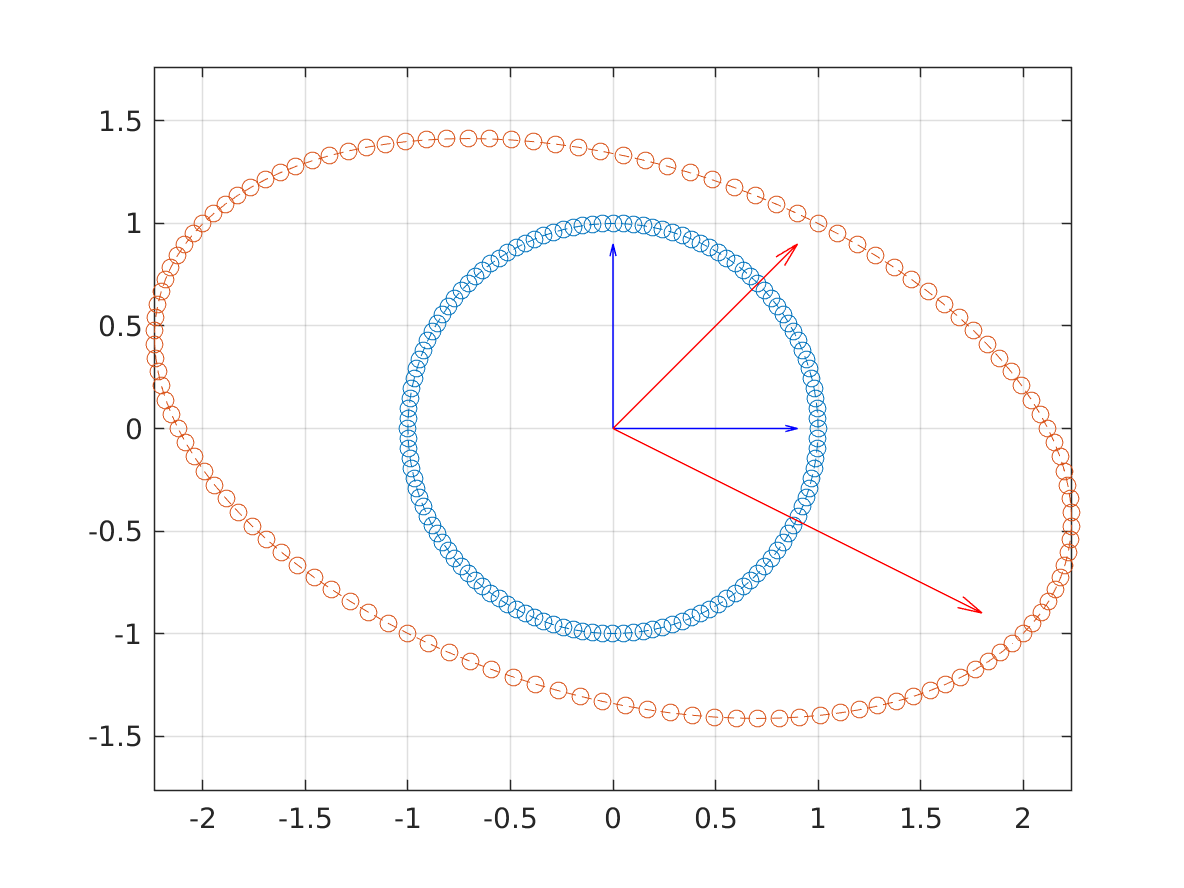

figure;
% draw the points
plot(x,y,'--o'); hold on;
plot(vv(1,:), vv(2,:),'--o');

% draw the arrows
basisX = x(basisIdx); basisY = y(basisIdx);
quiver(zeros(length(basisX),1), zeros(length(basisY),1), basisX, basisY,'b');
quiver(zeros(length(basisX),1), zeros(length(basisY),1), vv(1, basisIdx)', vv(2, basisIdx)','r');

% format the figure
grid on; axis equal;